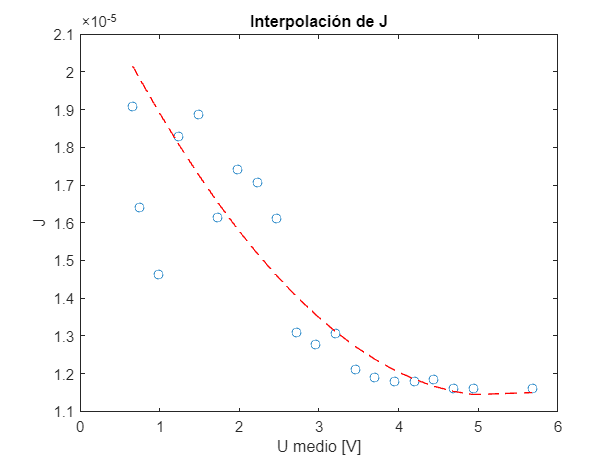

% LIMPIEZA Y CARGA DE DATOS
clear
close all

% Cargar datos del experimento
load('Experiment_identification.mat')

% Parámetros iniciales del motor (ajusta si es necesario)
J = 1.1378e-05;
b = 1.3760e-05;
K = 0.0172;
L = 0.0015;
R = 1.3; % Medido con el multímetro

% Media de los voltajes de la batería medido
V_nom = mean(data{2}.Values.Data);

% Corriente mínima que consume el driver
I_offset = 0.016; % [A] 

% Normalización de la entrada PWM
U_max = 255;

% Periodo de muestreo
DT = 0.01; % [s]

% Extracción de señales
U = (squeeze(data{4}.Values.Data)/U_max) * V_nom;
V = double(squeeze(data{3}.Values.Data)); % Velocidad [rad/s]
I = squeeze(data{1}.Values.Data) - I_offset; % Corriente [A]
t = (0:length(U)-1)' * DT;  % Vector de tiempo

% Definición del modelo inicial en espacio de estados
A = [-b/J K/J; -K/L -R/L];
B = [0; 1/L];
C = eye(2);
D = 0;
sys = idss(A, B, C, D, 'Ts', 0);

% --- IDENTIFICACIÓN POR ESCALÓN ---

% Tiempos de inicio de cada escalón (ajusta según tu experimento)
tiempos_escalon = 7.5:10:187.5; % segundos
N = length(U);

% Cálculo de índices de inicio de cada escalón
escalones_idx = round(tiempos_escalon / DT) + 1;
escalones_idx = [1 escalones_idx N]; % Incluye inicio y fin

num_escalones = length(escalones_idx) - 1;
K_ident = zeros(num_escalones,1);
b_ident = zeros(num_escalones,1);
J_ident = zeros(num_escalones,1);
L_ident = zeros(num_escalones,1);
R_ident = zeros(num_escalones,1); % Opcional
U_medio = zeros(num_escalones,1);
msys_steps = cell(num_escalones,1);

for i = 1:num_escalones
    idx_ini = escalones_idx(i);
    idx_fin = escalones_idx(i+1)-1;
    
    U_step = U(idx_ini:idx_fin);
    V_step = V(idx_ini:idx_fin);
    I_step = I(idx_ini:idx_fin);
    t_step = t(idx_ini:idx_fin);
    
    iddata_step = iddata([V_step I_step], U_step, DT);
    
    % Opciones de identificación
    opt = ssestOptions;
    opt.InitialState = 'zero';
    
    % Identificación
    msys_step = ssest(iddata_step, sys, opt);
    msys_steps{i} = msys_step;
    
    % Extrae parámetros identificados
    A_id = msys_step.A;
    B_id = msys_step.B;
    
    % L identificado
    L_ident(i) = 1 / B_id(2);
    
    % Dos formas de calcular K (deberían dar similar)
    K_ident_v1 = A_id(1,2) * J_ident(i);  % Desde A(1,2)
    K_ident_v2 = -A_id(2,1) * L_ident(i); % Desde A(2,1)
    
    % Usa el promedio o el que consideres más confiable
    K_ident(i) = K_ident_v2; % o K_ident_v2, o (K_ident_v1 + K_ident_v2)/2
    
    % J identificado
    J_ident(i) = K_ident(i) / A_id(1,2);  % Desde K y A(1,2)
    
    % b identificado  
    b_ident(i) = -A_id(1,1) * J_ident(i);
    
    % R identificado
    R_ident(i) = -A_id(2,2) * L_ident(i);
        
    U_medio(i) = mean(U_step);
end

% --- INTERPOLACIÓN DE PARÁMETROS ---
% Suponiendo que U_medio es un vector columna
n = length(U_medio);
pesos = linspace(1, 100, n)';

% Ajuste exponencial ponderado
fit_J = fit(U_medio, J_ident, 'poly2', 'Weights', pesos);
fit_b = fit(U_medio, b_ident, 'poly2', 'Weights', pesos);
fit_K = fit(U_medio, K_ident, 'poly2', 'Weights', pesos);
fit_L = fit(U_medio, L_ident, 'poly2', 'Weights', pesos);
fit_R = fit(U_medio, R_ident, 'poly2', 'Weights', pesos);

% --- VISUALIZACIÓN DE PARÁMETROS INTERPOLADOS ---
figure;
plot(U_medio, J_ident, 'o'); hold on;
plot(U_medio, fit_J(U_medio), 'r--'); hold on;
title('Interpolación de J');
xlabel('U medio [V]'); ylabel('J');

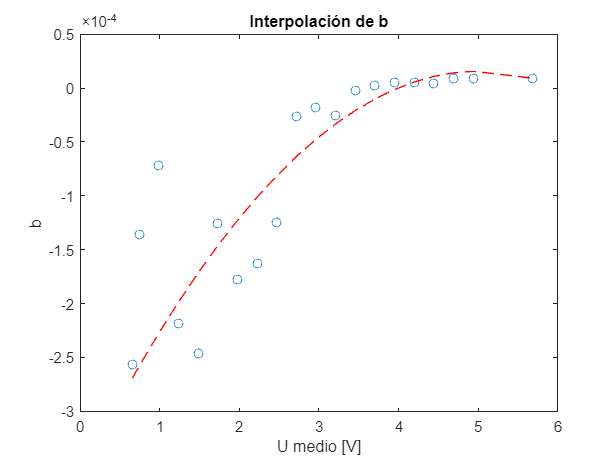


figure;
plot(U_medio, b_ident, 'o'); hold on;
plot(U_medio, fit_b(U_medio), 'r--'); hold on;
title('Interpolación de b');
xlabel('U medio [V]'); ylabel('b');

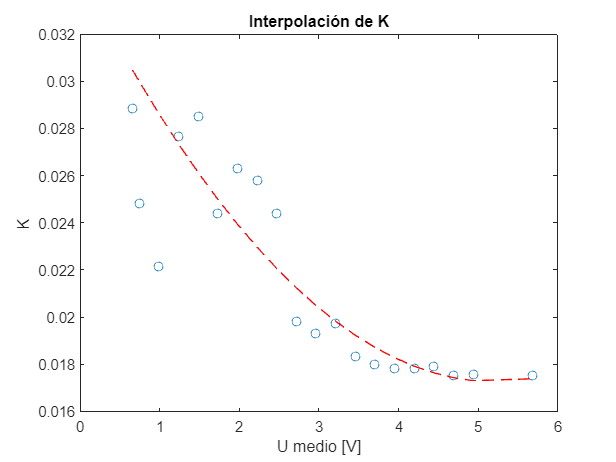


figure;
plot(U_medio, K_ident, 'o'); hold on;
plot(U_medio, fit_K(U_medio), 'r--'); hold on;
title('Interpolación de K');
xlabel('U medio [V]'); ylabel('K');

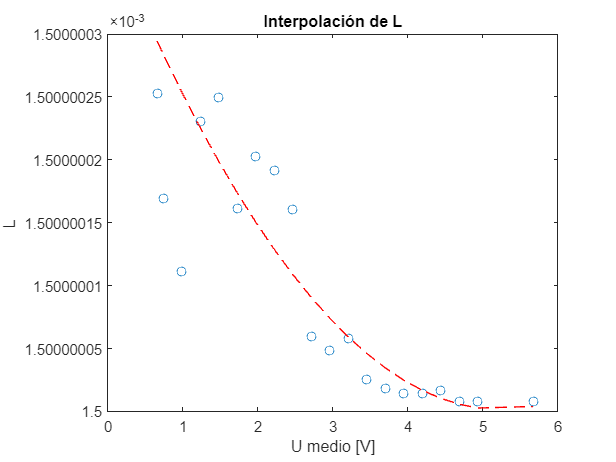


figure;
plot(U_medio, L_ident, 'o'); hold on;
plot(U_medio, fit_L(U_medio), 'r--'); hold on;
title('Interpolación de L');
xlabel('U medio [V]'); ylabel('L');

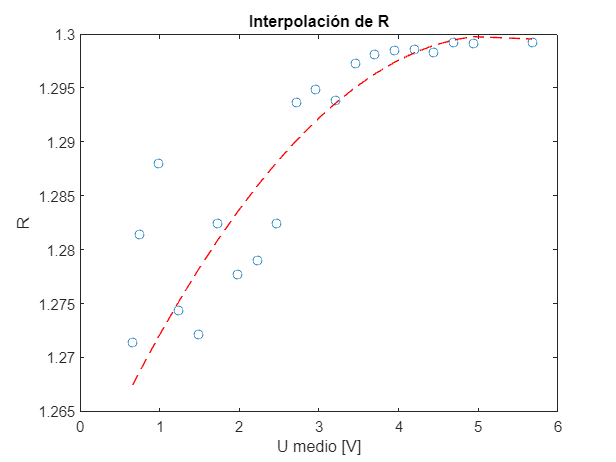


figure;
plot(U_medio, R_ident, 'o'); hold on;
plot(U_medio, fit_R(U_medio), 'r--'); hold on;
title('Interpolación de R');
xlabel('U medio [V]'); ylabel('R');

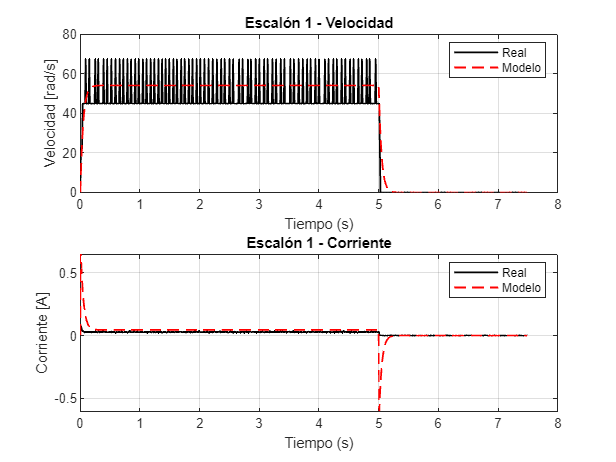

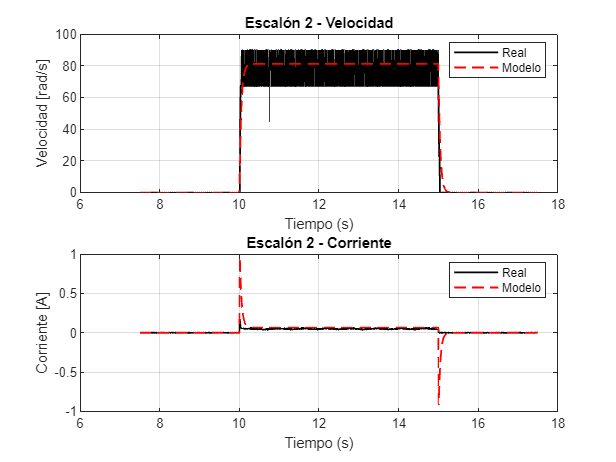

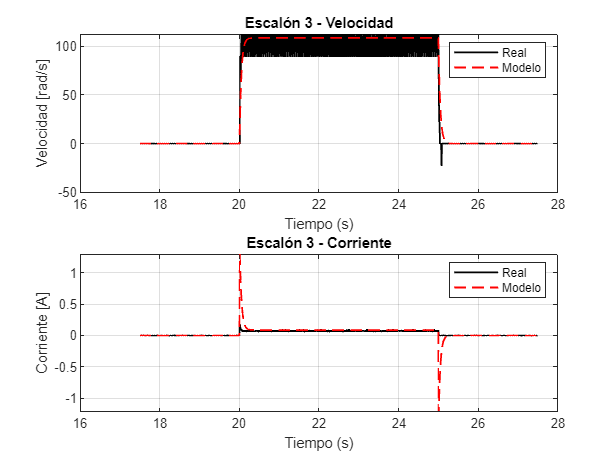

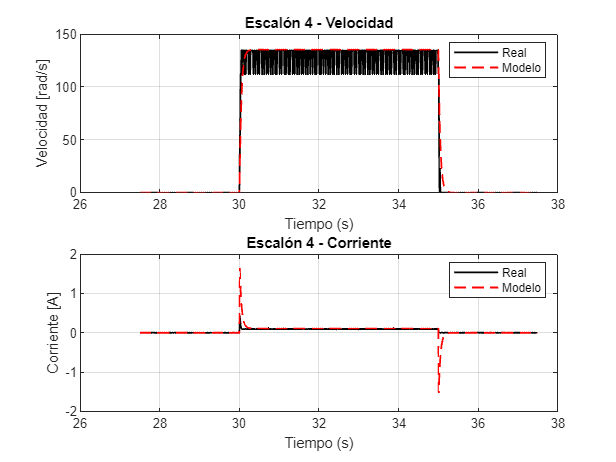

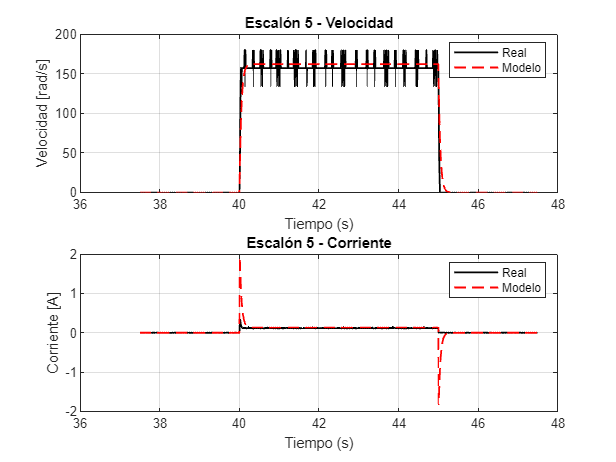

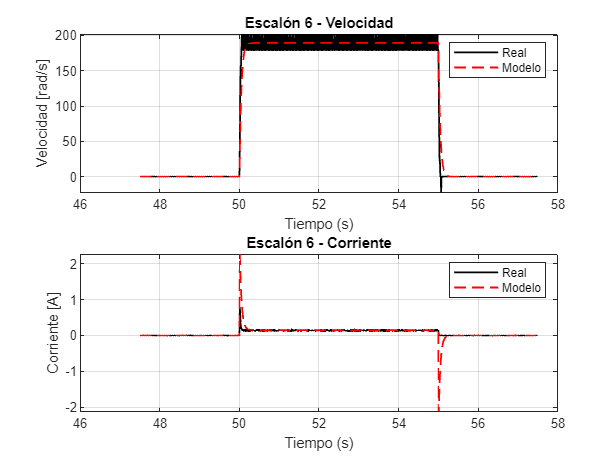

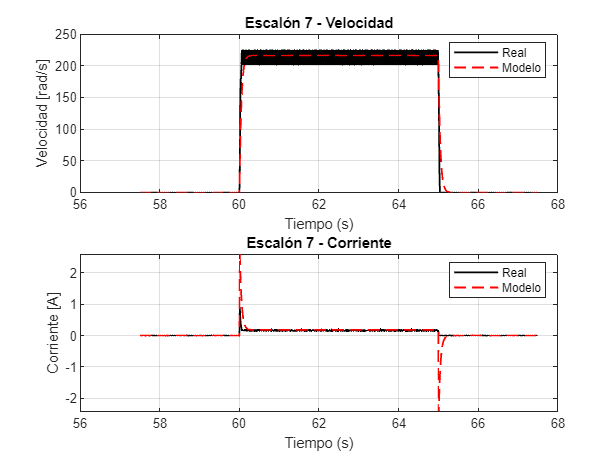

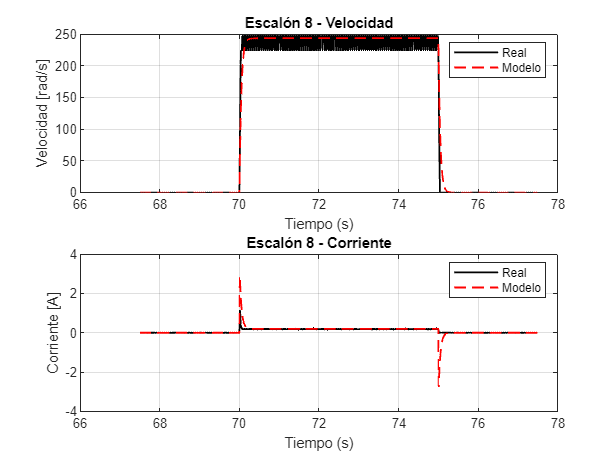


% --- RESPUESTA DE CADA SISTEMA IDENTIFICADO VS DATOS REALES ---
for i = 1:num_escalones
    idx_ini = escalones_idx(i);
    idx_fin = escalones_idx(i+1)-1;
    
    U_step = U(idx_ini:idx_fin);
    V_step = V(idx_ini:idx_fin);
    I_step = I(idx_ini:idx_fin);
    t_step = t(idx_ini:idx_fin);
    
    % Simula la respuesta del sistema identificado para este escalón
    [Y_sim, ~, ~] = lsim(msys_steps{i}, U_step, t_step);
    
    % Graficar comparación
    figure;
    subplot(2,1,1)
    plot(t_step, V_step, 'k', 'LineWidth', 1.2); hold on;
    plot(t_step, Y_sim(:,1), 'r--', 'LineWidth', 1.2);
    title(['Escalón ', num2str(i), ' - Velocidad']);
    legend('Real', 'Modelo');
    xlabel('Tiempo (s)');
    ylabel('Velocidad [rad/s]');
    grid on;
    
    subplot(2,1,2)
    plot(t_step, I_step, 'k', 'LineWidth', 1.2); hold on;
    plot(t_step, Y_sim(:,2), 'r--', 'LineWidth', 1.2);
    title(['Escalón ', num2str(i), ' - Corriente']);
    legend('Real', 'Modelo');
    xlabel('Tiempo (s)');
    ylabel('Corriente [A]');
    grid on;
end